clear all

%% Parameters
tspan = 2014:0.1:2314;
numSim = 100;
alpha_P1_vals = 4.0:0.1:7.0;

peakTvsInteraction = tempvs_alphaP1_fmax_fixed(numSim, tspan,0.0,alpha_P1_vals, 5.0);

simulation number = 10
Elapsed time is 87.605644 seconds.
simulation number = 20
Elapsed time is 95.699163 seconds.
simulation number = 30
Elapsed time is 96.115850 seconds.
simulation number = 40
Elapsed time is 87.872095 seconds.
simulation number = 50
Elapsed time is 85.291636 seconds.


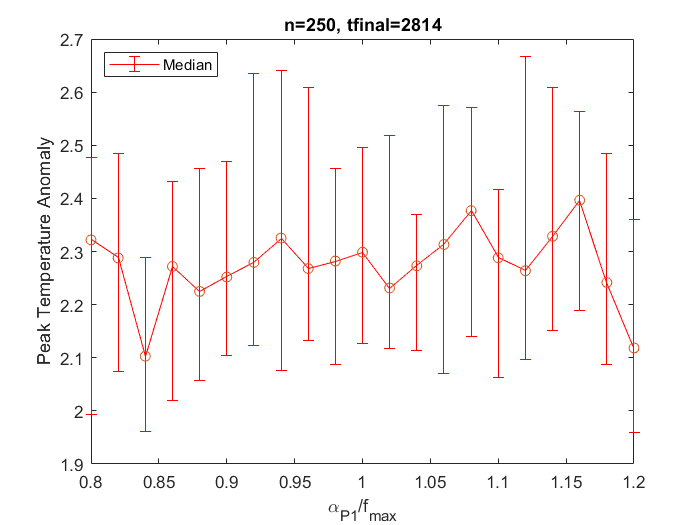

clf
medPeakT = median(peakTvsInteraction');
LowPeakT = quantile(peakTvsInteraction',0.25);
UpPeakT  = quantile(peakTvsInteraction',0.75);
temp_yneg = abs(medPeakT - LowPeakT);
temp_ypos = abs(medPeakT - UpPeakT);
errorbar(alpha_P1_vals./5,medPeakT, temp_yneg, temp_ypos,'Color','red')
hold on
scatter(alpha_P1_vals./5, medPeakT, 'Marker','o');

ylabel("Peak Temperature Anomaly")
xlabel("\alpha_{P1}/f_{max}")
legend("Median", "Location","northwest")
title("n=100, tfinal=2314")
hold off

peakTvsInteraction_heq1 = tempvs_alphaP1_fmax_fixed(numSim, tspan,1.0,alpha_P1_vals, 5.0);

clf
medPeakT = median(peakTvsInteraction_heq1');
LowPeakT = quantile(peakTvsInteraction_heq1',0.25);
UpPeakT  = quantile(peakTvsInteraction_heq1',0.75);
temp_yneg = abs(medPeakT - LowPeakT);
temp_ypos = abs(medPeakT - UpPeakT);
errorbar(alpha_P1_vals./5,medPeakT, temp_yneg, temp_ypos,'Color','red')
hold on
scatter(alpha_P1_vals./5, medPeakT, 'Marker','o');

ylabel("Peak Temperature Anomaly")
xlabel("\alpha_{P1}/f_{max}")
legend("Median", "Location","northwest")
title("n=100, tfinal=2314")
hold off

1==a

Unrecognized function or variable 'a'.

% clf
% [sorted_diff, sortIdx] = sort(peakTvsInteraction.interaction_ratio);
% temp_yneg = abs(peakTvsInteraction.avg_ - peakTvsInteraction.std_);
% temp_ypos = abs(peakTvsInteraction.std_);
% errorbar(sorted_diff,peakTvsInteraction.avg_(sortIdx), peakTvsInteraction.std_(sortIdx),'Color', 'red')
% xlabel("\alpha_{P1}/f_{max}")
% ylabel("Peak Temperature anomaly")
% title('h=1')
% legend("Avg & std", "Location", "northwest")
%xlim([0.95,1.05])

% clf
% [sorted_diff, sortIdx] = sort(peakTvsInteraction.interaction_ratio);
% temp_yneg = abs(peakTvsInteraction.med - peakTvsInteraction.iq25);
% temp_ypos = abs(peakTvsInteraction.med - peakTvsInteraction.iq75);
% %errorbar(peakTvsIneq.omega_diff,peakTvsIneq.avg_, temp_yneg, temp_ypos)
% errorbar(sorted_diff,peakTvsInteraction.med(sortIdx), temp_yneg(sortIdx), temp_ypos(sortIdx),'Color', 'red')
% xlabel("\alpha_{P1}/f_{max}")
% ylabel("Peak Temperature Anomaly")
% legend("Median", "Location", "northwest")
% title('h=1')

hvals = peakTvsInteraction.homophily_val;
T_med = peakTvsInteraction.median_;
interact_ = peakTvsInteraction.interaction_ratio;



% save('/home/jmenard/S2019_rpt_sociodynamics_data/peakTvsInteraction_h0/peakTvsInteraction_heq0.mat','peakTvsInteraction')